# Dual-Polarity GRAPPA (DPG) reconstruction

Rex Fung, July 10th, 2024

## Load in params

Sequence design params

setGREparams; setEPIparams;

% Params defined at scanner
% What you set toppe CV 8 to when running the scan
Nloops_acs = 10;
Nloops = 10;

Nframes_acs = Nloops_acs*NframesPerLoop*2;
Nframes = Nloops*NframesPerLoop;

% Filenames
datdir = '/mnt/storage/rexfung/20240719dpepi/';
fn_gre = strcat(datdir,'gre.h5');
fn_cal = strcat(datdir,'cal.h5');
fn_loop = strcat(datdir,'loop.h5');
fn_adc = sprintf('adc/adc%d.mod',Nx);

% Options
showEPIphaseDiff = true;

## Load in raw data

Read using Matteo's scripts

ksp_gre_raw = read_archive(fn_gre);

Reading ScanArchive header from '/mnt/storage/rexfung/20240719dpepi/gre.h5'
Datatype not specified assuming that the data is a "raw file" 
RFS: header release = 30
psd_iname = 'toppe'
nframes=120  frame_size=120  nphases=1  nechoes=1  nslices=23  nreceivers=32
data size = 84.7872 [MB] (single precision)
Loading ScanArchive data from '/mnt/storage/rexfung/20240719dpepi/gre.h5'
Loading controls
Loading frames
Sorting data
psd_iname = 'toppe'
full (slow) reordering in loop
slice_order = 1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23


ksp_cal_raw = read_archive(fn_cal);

Reading ScanArchive header from '/mnt/storage/rexfung/20240719dpepi/cal.h5'
Datatype not specified assuming that the data is a "raw file" 
RFS: header release = 30
psd_iname = 'toppe'
nframes=240  frame_size=180  nphases=1  nechoes=1  nslices=2  nreceivers=32
data size = 22.1184 [MB] (single precision)
Loading ScanArchive data from '/mnt/storage/rexfung/20240719dpepi/cal.h5'
Loading controls
Loading frames
Sorting data
psd_iname = 'toppe'
full (slow) reordering in loop
slice_order = 1  2


ksp_loop_raw = read_archive(fn_loop);

Reading ScanArchive header from '/mnt/storage/rexfung/20240719dpepi/loop.h5'
Datatype not specified assuming that the data is a "raw file" 
RFS: header release = 30
psd_iname = 'toppe'
nframes=600  frame_size=180  nphases=1  nechoes=1  nslices=41  nreceivers=32
data size = 1133.57 [MB] (single precision)
Loading ScanArchive data from '/mnt/storage/rexfung/20240719dpepi/loop.h5'
Loading controls
Loading frames
Sorting data
psd_iname = 'toppe'
full (slow) reordering in loop
slice_order = 1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41



% Save dimension info
[Nfid, Ncoils] = size(ksp_cal_raw,2,5);

% Print max real and imag parts to check for reasonable magnitude
fprintf('Max real part of gre data: %d\n', max(real(ksp_gre_raw(:))))

Max real part of gre data: 5752


fprintf('Max imag part of gre data: %d\n', max(imag(ksp_gre_raw(:))))

Max imag part of gre data: 7244


fprintf('Max real part of cal data: %d\n', max(real(ksp_cal_raw(:))))

Max real part of cal data: 7367


fprintf('Max imag part of cal data: %d\n', max(imag(ksp_cal_raw(:))))

Max imag part of cal data: 7620


fprintf('Max real part of loop data: %d\n', max(real(ksp_loop_raw(:))))

Max real part of loop data: 5279


fprintf('Max imag part of loop data: %d\n', max(imag(ksp_loop_raw(:))))

Max imag part of loop data: 5588


## Preprocessing

% Permute and reshape to to [Nfid, Ncoils, ...]
ksp_gre = permute(squeeze(ksp_gre_raw),[2,4,1,3]);
ksp_cal = permute(squeeze(ksp_cal_raw),[2,4,1,3]);
ksp_loop = permute(squeeze(ksp_loop_raw),[2,4,1,3]);

% Discard leading blank space
ksp_gre = ksp_gre(:,:,(size(ksp_gre,3) + 1):end);
ksp_cal = ksp_cal(:,:,(size(ksp_cal,3) + 1):end);
ksp_loop = ksp_loop(:,:,(size(ksp_loop,3) + 1):end);

% Split first (positive readout) and second (negative readout) half of data
ksp_gre_plus = ksp_gre(:,:,1:end/2);
ksp_gre_minus = ksp_gre(:,:,(end/2 + 1):end);
ksp_cal_plus = ksp_cal(:,:,1:end/2);
ksp_cal_minus = ksp_cal(:,:,(end/2 + 1):end);

% Extract calibration data from GRE scans
ksp_gre_cal_plus = ksp_gre_plus(:,:,1:Ny_gre);
ksp_gre_cal_minus = ksp_gre_minus(:,:,1:Ny_gre);
ksp_gre_plus = ksp_gre_plus(:,:,(Ny_gre + 1):end);
ksp_gre_minus = ksp_gre_minus(:,:,(Ny_gre + 1):end);

## Preprocessing: reshaping dimensions

% Reshape and permute GRE data
% [Nx_gre, Ny_gre, Nz_gre, Ncoils]
ksp_gre_plus = reshape(ksp_gre_plus,Nx_gre,Ncoils,Ny_gre,Nz_gre);
ksp_gre_plus = permute(ksp_gre_plus,[1 3 4 2]);
ksp_gre_minus = reshape(ksp_gre_minus,Nx_gre,Ncoils,Ny_gre,Nz_gre);
ksp_gre_minus = permute(ksp_gre_minus,[1 3 4 2]);

% Reshape and permute EPI calibration data (a single frame w/o blips)
% [Nfid, Ny/Nsegments, Nsegments, Nz, Ncoils]
ksp_cal_plus = reshape(ksp_cal_plus,Nfid,Ncoils,Ny/Nsegments,Nsegments);
ksp_cal_plus = permute(ksp_cal_plus,[1 3 4 5 2]);
ksp_cal_minus = reshape(ksp_cal_minus,Nfid,Ncoils,Ny/Nsegments,Nsegments);
ksp_cal_minus = permute(ksp_cal_minus,[1 3 4 5 2]);

% Reshape and permute EPI loop data (alternating ro polarities through time)
% [Nfid, Ny/Nsegments, Nsegments, Nz, Nframes_acs, Ncoils]
ksp_loop = reshape(ksp_loop,Nfid,Ncoils,Ny/Nsegments,Nsegments,Nz,Nframes_acs);
ksp_loop = permute(ksp_loop,[1 3 4 5 6 2]);

## Quality check: GRE images

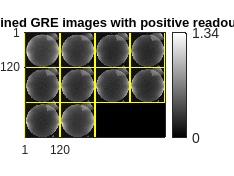

figure; im(sqrt(sum(abs(toppe.utils.ift3(ksp_gre_plus)).^2,4)),'cbar');
title('RSOS coil-combined GRE images with positive readout polarity');

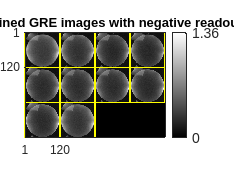

figure; im(sqrt(sum(abs(toppe.utils.ift3(ksp_gre_minus)).^2,4)),'cbar');
title('RSOS coil-combined GRE images with negative readout polarity');

## Sort apart the ACS data into + and - polarities

% Average + and - polarity frames across time
ksp_acs_plus = squeeze(mean(ksp_loop(:,:,:,:,1:2:end,:),5));
ksp_acs_minus = squeeze(mean(ksp_loop(:,:,:,:,2:2:end,:),5));

% Stack both polarities into one tensor for convenience
ksp_loop = [reshape(ksp_acs_plus,[1 size(ksp_acs_plus)]);...
           reshape(ksp_acs_minus,[1 size(ksp_acs_minus)])];

## Visualize

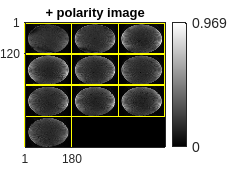

% Swap every other line
tmp = ksp_acs_minus(:,2:2:end,:,:,:);
ksp_acs_minus(:,2:2:end,:,:,:) = ksp_acs_plus(:,2:2:end,:,:,:);
ksp_acs_plus(:,2:2:end,:,:,:) = tmp;
clear tmp;

% Sort segments/shots into proper locations
ksp_acs_plus_sorted = zeros(Nfid,Ny,Nz,Ncoils);
ksp_acs_minus_sorted = zeros(Nfid,Ny,Nz,Ncoils);
for seg = 1:Nsegments
    ksp_acs_plus_sorted(:,seg:Nsegments:end,:,:,:) = squeeze(ksp_acs_plus(:,:,seg,:,:,:));
    ksp_acs_minus_sorted(:,seg:Nsegments:end,:,:,:) = squeeze(ksp_acs_minus(:,:,seg,:,:,:));
end

% Look at the corresponding RSOS images
figure;
im(sqrt(sum(abs(toppe.utils.ift3(ksp_acs_plus_sorted)).^2,4)),'cbar')
title('+ polarity image');

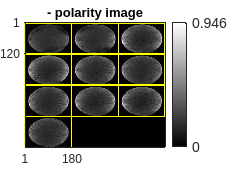

figure;
im(sqrt(sum(abs(toppe.utils.ift3(ksp_acs_minus_sorted)).^2,4)),'cbar')
title('- polarity image');

## Estimate linear phase offset of ACS data

Estimated offset from center of k-space (samples): -1.284375


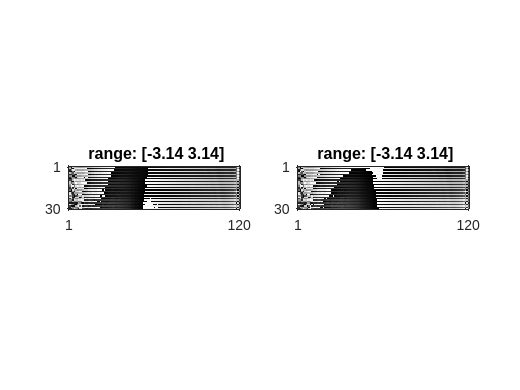

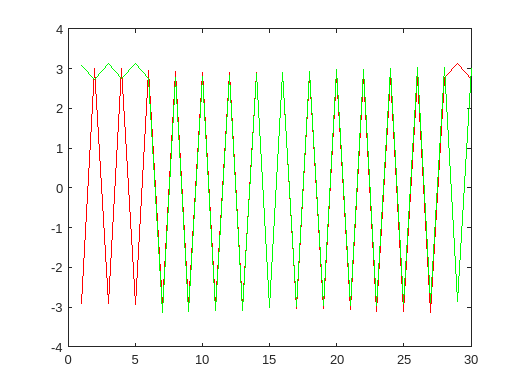

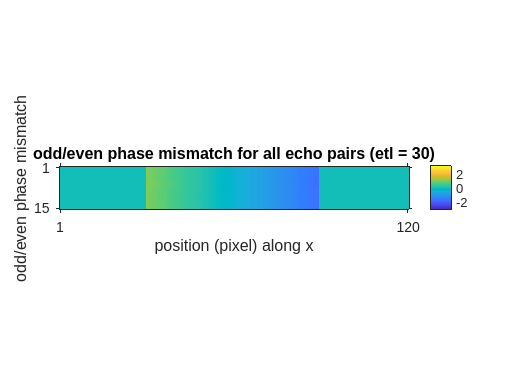

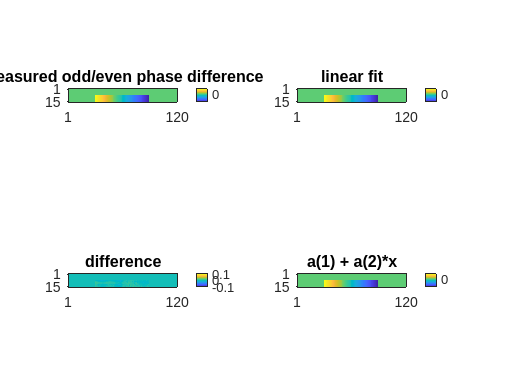

Constant phase offset (radians): -0.369024


Linear term (radians/fov): -5.669594


Estimated offset from center of k-space (samples): -0.872396


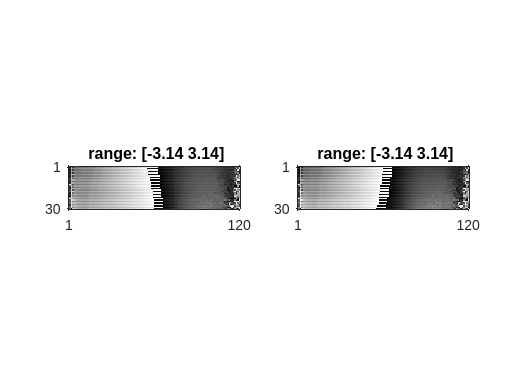

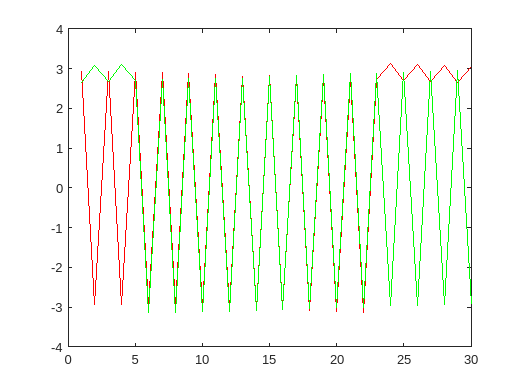

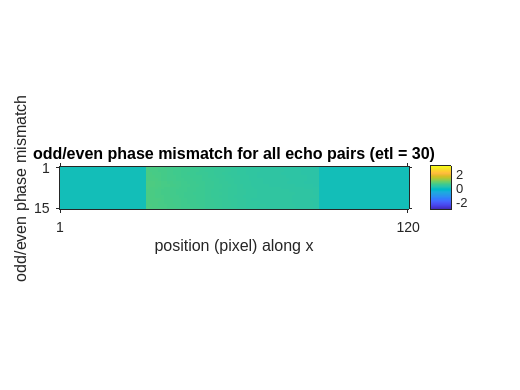

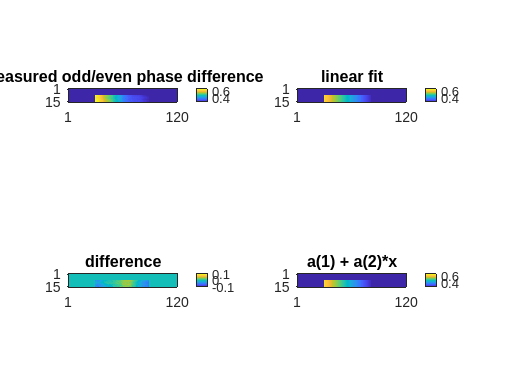

Constant phase offset (radians): 0.432190


Linear term (radians/fov): -0.803271


% Stack both polarities into one tensor for convenience
ksp_cal = [reshape(ksp_cal_plus,[1 size(ksp_cal_plus)]);...
                  reshape(ksp_cal_minus,[1 size(ksp_cal_minus)])];

kxo_locs = zeros(2,Nfid);
kxe_locs = zeros(2,Nfid);
phase_coeffs = zeros(2,2);

for polarity = 1:2 % 1 = positive, 2 = negative
    % Estimate k-space center offset due to gradient delay
    cal_data = reshape(abs(squeeze(ksp_cal(polarity,:,:,:,:,:))),Nfid,Ny/Nsegments,Nsegments*Ncoils);
    cal_data(:,2:2:end,:) = flip(cal_data(:,2:2:end,:),1); % every other line is flipped in EPI
    [M, I] = max(cal_data,[],1);
    delay = 2*mean(I,'all') - Nfid; delay = -delay;
    fprintf('Estimated offset from center of k-space (samples): %f\n', delay);
    
    % retrieve sample locations from .mod file with adc info
    [rf,gx,gy,gz,desc,paramsint16,pramsfloat,hdr] = toppe.readmod(fn_adc);
    [kxo, kxe] = toppe.utils.getk(sysGE, fn_adc, Nfid, delay);
    kxo_locs(polarity,:) = kxo;
    kxe_locs(polarity,:) = kxe;

    % Extract even number of lines (in case ETL is odd)
    ETL_even = size(ksp_cal,3) - mod(size(ksp_cal,3),2);
    oephase_data = reshape(squeeze(ksp_cal(polarity,:,1:ETL_even,:,:,:)),...
                           Nfid, ETL_even, Nsegments*Ncoils);
    
    % EPI ghost correction phase offset values
    oephase_data = hmriutils.epi.rampsampepi2cart(oephase_data, kxo, kxe, Nx, fov(1)*100, 'nufft');
    oephase_data = ifftshift(ifft(fftshift(oephase_data),Nx,1));
    [a, th] = hmriutils.epi.getoephase(oephase_data,showEPIphaseDiff);
    fprintf('Constant phase offset (radians): %f\n', a(1));
    fprintf('Linear term (radians/fov): %f\n', a(2));

    phase_coeffs(:,polarity) = a;
end

## Apply linear phase correction to ACS data

ksp_acs_gridded = zeros(2,Nx,Ny/Nsegments,Nsegments,Nz,Ncoils);
ksp_acs_corrected = zeros(2,Nx,Ny/Nsegments,Nsegments,Nz,Ncoils);

for polarity = 1:2 % 1 = positive, 2 = negative
    kxo = kxo_locs(polarity,:);
    kxe = kxe_locs(polarity,:);

    % grid data
    tmp = hmriutils.epi.rampsampepi2cart(squeeze(ksp_loop(polarity,:,:,:,:,:)),...
                                          kxo, kxe, Nx, fov(1)*100, 'nufft');
    ksp_acs_gridded(polarity,:,:,:,:,:) = tmp;

    % phase correct
    ksp_acs_corrected(polarity,:,:,:,:,:) = hmriutils.epi.epiphasecorrect(tmp,phase_coeffs(:,polarity));
end

## Allocate segments into proper locations

ksp_acs_source = zeros(2,Nx,Ny,Nz,Ncoils);
ksp_acs_target = zeros(2,Nx,Ny,Nz,Ncoils);

for seg = 1:Nsegments
    ksp_acs_source(:,:,seg:Nsegments:end,:,:) = squeeze(ksp_acs_gridded(:,:,:,seg,:,:));
    ksp_acs_target(:,:,seg:Nsegments:end,:,:) = squeeze(ksp_acs_corrected(:,:,:,seg,:,:));
end

## Visualize

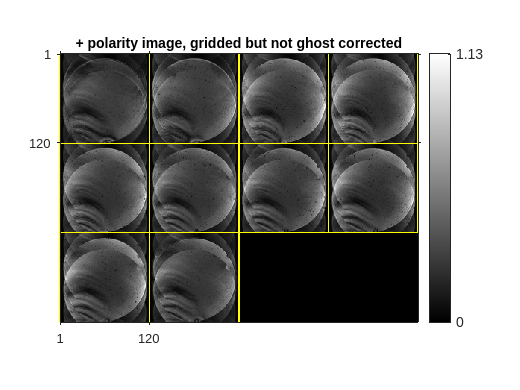

% Look at the corresponding RSOS images
figure;
im(sqrt(sum(abs(toppe.utils.ift3(squeeze(ksp_acs_source(1,:,:,:,:)))).^2,4)),'cbar')
title('+ polarity image, gridded but not ghost corrected');

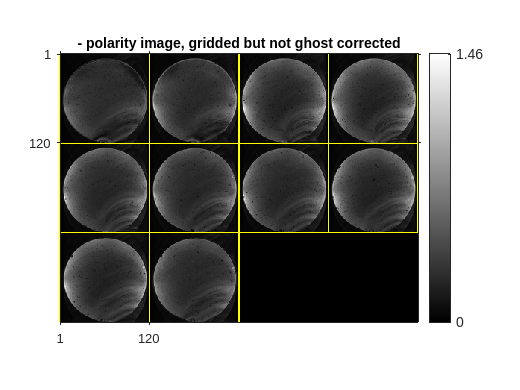

figure;
im(sqrt(sum(abs(toppe.utils.ift3(squeeze(ksp_acs_source(2,:,:,:,:)))).^2,4)),'cbar')
title('- polarity image, gridded but not ghost corrected');

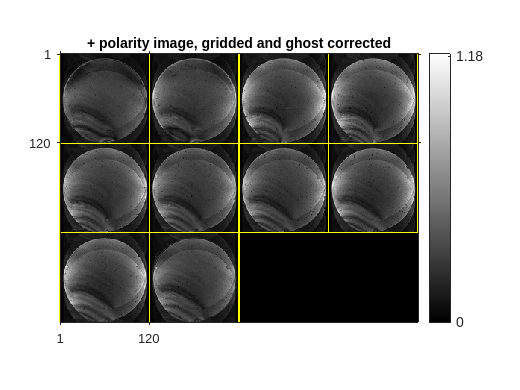


figure;
im(sqrt(sum(abs(toppe.utils.ift3(squeeze(ksp_acs_target(1,:,:,:,:)))).^2,4)),'cbar')
title('+ polarity image, gridded and ghost corrected');

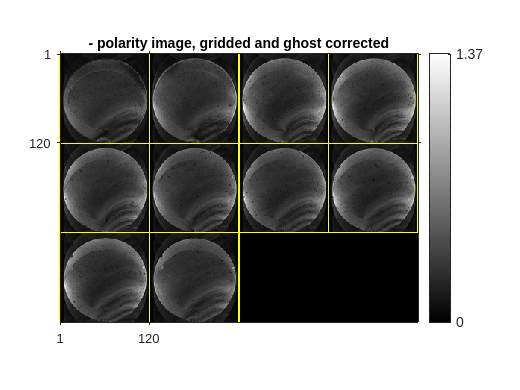

figure;
im(sqrt(sum(abs(toppe.utils.ift3(squeeze(ksp_acs_target(2,:,:,:,:)))).^2,4)),'cbar')
title('- polarity image, gridded and ghost corrected');

## Compute DPG kernel weights

## Reconstruct k-space

## Enforce low-rankness

## Display